Импорт данных

spectra = importdata('spectra.csv');
starNames = importdata('star_names.csv');
lambdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');

Определим константы

lambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/c

 

Определим диапазон длин волн

nObs = size(spectra, 1);
lambdaEnd = lambdaStart + (nObs - 1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

Рассчитаем скорости звезд относительно Земли

nStars = size(starNames, 1);
speed = zeros(1, nStars);
i = 1:nStars;
s = spectra(:, i);
[sHa, idx] = min(s);
lambdaHa = lambda(idx);
z = (lambdaHa / lambdaPr) - 1;
speed(i) = z * speedOfLight;
speed = speed';
movaway = starNames(speed > 0);

 Построим график

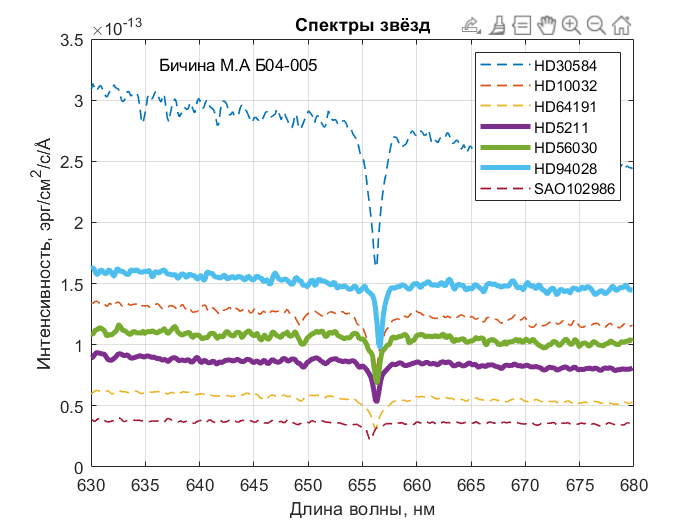

fg = figure;
for i = 1:nStars
    if speed(i) > 0        
        plot(lambda, spectra(:, i), 'linewidth', 3)
    elseif speed(i) <= 0
        plot(lambda, spectra(:, i), '--', 'linewidth', 1)
    end
   
    hold on
end
legend(starNames)
title('Спектры звёзд')
xlabel('Длина волны, нм')
ylabel(['Интенсивность, эрг/см^2/с/', char(197)])
text(lambdaStart * 7 / 8 + lambdaEnd / 8, max(max(spectra) * 1.05), 'Бичина М.А Б04-005')
grid on
set(fg, 'visible', 'on')
hold off

 Сохраним график

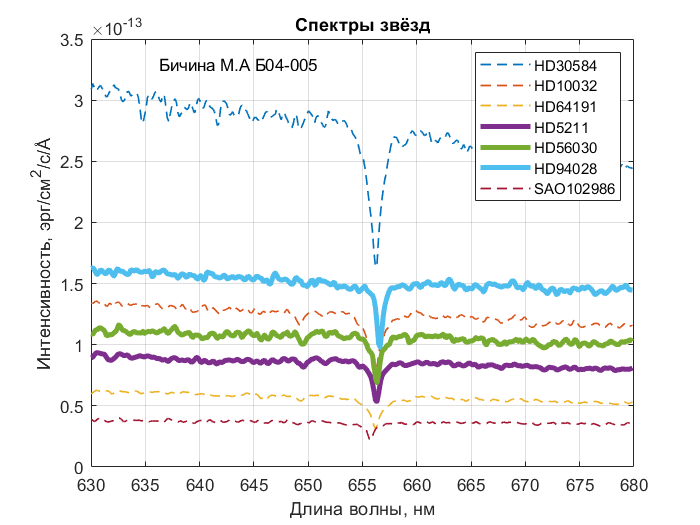

saveas(fg, 'figure.png')